# CAPÍTULO 13 - SISTEMAS DE BARRAS MÁS ALLÁ DEL LÍMITE ELÁSTICO

Explora la aparición de fluencia y la carga límite en barras paralelas, flexión de una sección o torsión circular.

Dimensión: plasticidad de barras paralelas o de una sección en flexión/torsión pura. No calcula el colapso plástico de un marco espacial completo.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="flexion", "axial" o "torsion". En flexión, niveles y anchuras describen la sección: la anchura se interpola linealmente. En axial, Lb y Fb representan barras paralelas. En torsión, R y ri son radios exterior e interior.

modo="flexion";
E=210e9; G=80e9; sigmaFluencia=250e6; tauFluencia=145e6;
niveles=[-.08 0 .08]; anchuras=[.08 .08 .08];
curvaturaMax=.10;
Lb=[1 1.5 2]; Fb=[200 300 250]*1e-6; desplazamientoMax=.004;
R=.025; ri=0; longitudEje=1; giroPorLongitudMax=.5;
pasos=101;

## 2. Ley ideal elastoplástica


$$\sigma=\max(-\sigma_Y,\min(E\varepsilon,\sigma_Y)),\qquad \tau=\max(-\tau_Y,\min(G\gamma,\tau_Y))$$



$$P_{lim}=\sum_iF_i\sigma_Y,\qquad M_{pl}=\sigma_Y\int|y-y_{pl}|\,dA,\qquad T_{pl}=\frac{2\pi}{3}\tau_Y(R^3-r_i^3)$$


La tensión deja de aumentar al alcanzar fluencia. La estructura puede seguir soportando carga mientras otras fibras o barras permanecen elásticas. El control por desplazamiento o curvatura permite seguir esa evolución sin intentar invertir una rigidez que llega a cero.

assert(all([E G sigmaFluencia tauFluencia]>0) && pasos>=3,'Material invalido.');
if modo=="axial"
    assert(numel(Lb)==numel(Fb) && all(Lb>0 & Fb>0) && desplazamientoMax>0,'Barras invalidas.');
    parametro=linspace(0,desplazamientoMax,pasos)';
    tensiones=max(-sigmaFluencia,min(E*parametro./Lb,sigmaFluencia));
    respuesta=tensiones*Fb(:); limite=sum(Fb)*sigmaFluencia;
    resultado=struct('parametro',parametro,'respuesta',respuesta,'limite',limite,'tensiones',tensiones);
elseif modo=="flexion"
    assert(all(diff(niveles)>0) && all(anchuras>=0) && curvaturaMax>0,'Seccion invalida.');
    y=linspace(min(niveles),max(niveles),2001)'; b=interp1(niveles,anchuras,y);
    area=trapz(y,b); assert(area>0,'Area nula.'); yc=trapz(y,y.*b)/area;
    inercia=trapz(y,(y-yc).^2.*b); acumulada=cumtrapz(y,b);
    [unicos,ix]=unique(acumulada); yplastico=interp1(unicos,y(ix),area/2);
    limite=sigmaFluencia*trapz(y,abs(y-yplastico).*b);
    parametro=linspace(0,curvaturaMax,pasos)'; respuesta=zeros(size(parametro));
    for j=2:pasos
        k=parametro(j);
        equilibrio=@(y0) trapz(y,max(-sigmaFluencia,min(-E*k*(y-y0),sigmaFluencia)).*b);
        y0=fzero(equilibrio,[min(y)-(max(niveles)-min(niveles)) max(y)+(max(niveles)-min(niveles))]);
        sigma=max(-sigmaFluencia,min(-E*k*(y-y0),sigmaFluencia));
        respuesta(j)=-trapz(y,sigma.*(y-yc).*b);
    end
    resultado=struct('parametro',parametro,'respuesta',respuesta,'limite',limite, ...
        'sigma',sigma,'y',y,'inercia',inercia,'centro',yc);
else
    assert(modo=="torsion" && R>ri && ri>=0 && longitudEje>0 && giroPorLongitudMax>0,'Eje invalido.');
    rho=linspace(ri,R,2001)'; parametro=linspace(0,giroPorLongitudMax,pasos)';
    respuesta=zeros(size(parametro));
    for j=1:pasos
        tau=min(G*parametro(j)*rho,tauFluencia);
        respuesta(j)=2*pi*trapz(rho,tau.*rho.^2);
    end
    limite=2*pi*tauFluencia*(R^3-ri^3)/3;
    resultado=struct('parametro',parametro,'respuesta',respuesta,'limite',limite,'tau',tau,'rho',rho);
end
disp("Carga o momento limite: "+limite);

Carga o momento limite: 128000


disp("Respuesta al ultimo incremento: "+respuesta(end));

Respuesta al ultimo incremento: 127055.2006


## 3. Curva y distribución

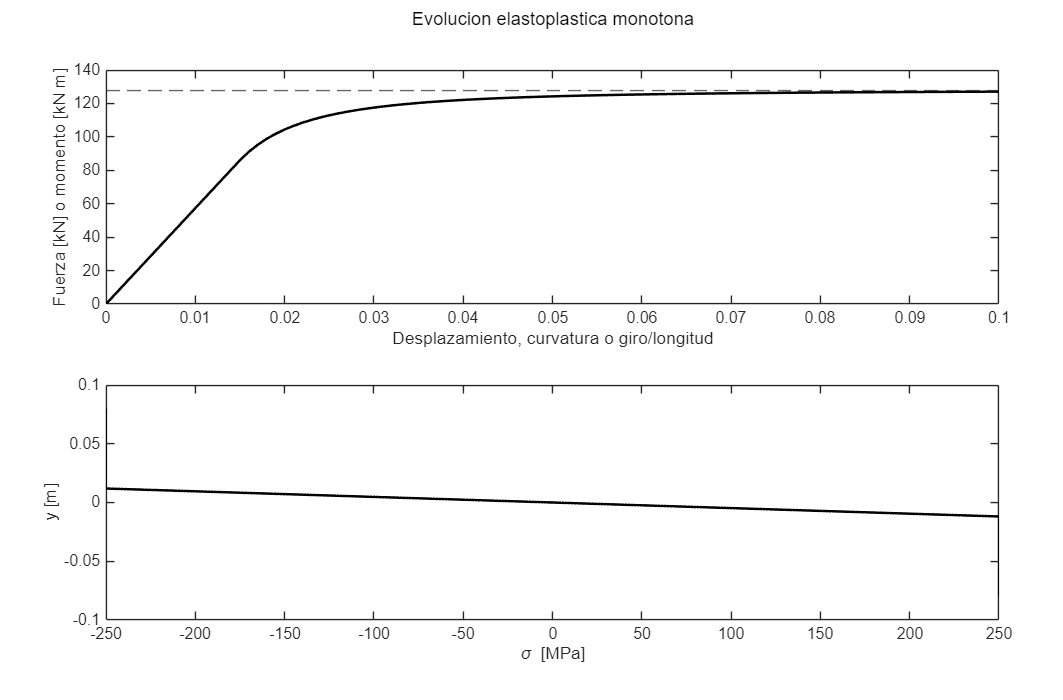

[figura,ejes]=rm_figura(2,'Evolucion elastoplastica monotona');
plot(ejes(1),parametro,respuesta/1000,'k-','LineWidth',1.5);
yline(ejes(1),limite/1000,'--'); xlabel(ejes(1),'Desplazamiento, curvatura o giro/longitud');
ylabel(ejes(1),'Fuerza [kN] o momento [kN m]');
if modo=="flexion"
    plot(ejes(2),sigma/1e6,y,'k-','LineWidth',1.5); xlabel(ejes(2),'\sigma [MPa]'); ylabel(ejes(2),'y [m]');
elseif modo=="torsion"
    plot(ejes(2),rho,tau/1e6,'k-','LineWidth',1.5); xlabel(ejes(2),'Radio [m]'); ylabel(ejes(2),'\tau [MPa]');
else
    plot(ejes(2),parametro*1000,tensiones/1e6,'LineWidth',1.2); xlabel(ejes(2),'\delta [mm]'); ylabel(ejes(2),'\sigma [MPa]');
end

## Funciones utilizadas

min y max: limitan valores por arriba y abajo. Aquí representan la meseta de fluencia ideal.

fzero: busca una raíz de una función. Aquí encuentra la posición neutra que conserva esfuerzo axial nulo.

interp1: interpola datos de una variable. Aquí construye la anchura de sección y el eje plástico.

trapz: aproxima una integral. Aquí suma tensiones para obtener fuerzas y momentos; refina la malla para comprobar convergencia.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Material ideal elastoplástico simétrico y carga monótona. Barras paralelas con desplazamiento común; flexión pura de una sección descrita por anchura frente a altura; torsión de sección circular. No representa descarga, endurecimiento, ciclos plásticos ni colapso general de un marco.

Conexión con lo anterior: Reutiliza las distribuciones elásticas de los capítulos 1, 4 y 5. La carga límite requiere equilibrio además del límite de tensión del material.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 13: calculo completado.');

Capitulo 13: calculo completado.
